# CÁLCULO NUMÉRICO

# PRÁCTICA 4 · TEMA 6 · DERIVACIÓN

GRUPO:  **GRUPO 4 **

NOMBRES: 

**    JUAN CANO **

**    DAVID MARÍN **

**    PABLO MENDIETA **

**    DAVID MORENO**

FECHA: **18 / 02 / 24**

## P04_T06_P01. Primera y segunda derivadas en puntos equiespaciados

**a) **Función adjuntada: `[yd,ydd] = PrimSegDeriv(x,y)`

Se ha utilidado el método de **diferencia central en 2 puntos : **$f^{\prime } \left(x_i \right)=\frac{f\left(x_{i+1} \right)-f\left(x_{i-1} \right)\;}{2h}$ 

con un **error de truncamiento de** $O\left(h^2 \right)$

**b)**

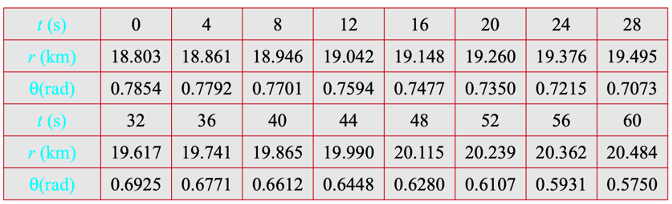

clc, clear, clf 

% Datos del problema 
t = 0:4:60; % segundos
r = [18.803 18.861 18.946 19.042 19.148 19.260 19.376 19.495 19.617 19.741 19.865 19.990 20.115 20.239 20.362 20.484]; % kilometros  
theta = [0.7854 0.7792 0.7701 0.7594 0.7477 0.7350 0.7215 0.7073 0.6925 0.6771 0.6612 0.6448 0.6280 0.6107 0.5931 0.5750]; % radianes

% Cálculo de las primeras y segundas derivadas de r y theta.
[rd, rdd] = PrimSegDeriv(t, r);
[thetad, thetadd] = PrimSegDeriv(t, theta);

 
$$v=\sqrt{{\left(\frac{\textrm{dr}}{\textrm{dt}}\right)}^2 +{\left(r\frac{d\theta }{\textrm{dt}}\right)}^2 }$$
     
$$a=\sqrt{{\left\lbrack \frac{d^2 r}{dt^2 }-r\left(\frac{d^2 r}{dt^2 }-r{\left(\frac{d\theta }{\textrm{dt}}\right)}^2 \right)\right\rbrack }^2 +{\left\lbrack r\frac{d^2 \theta }{dt^2 }+2\frac{\textrm{dr}}{\textrm{dt}}\cdot \frac{d\theta }{\textrm{dt}}\right\rbrack }^2 }$$
    

v = sqrt(rd.^2 + (r.* thetad).^2);
a = sqrt((rdd - r.*(rdd - r.*thetad.^2)).^2 + (r.*thetadd + 2.*rd.*thetad).^2);

% tabla con las velocidades y aceleraciones
T = table(t', v', a');
T.Properties.VariableNames = {'t(s)', 'v(km/s)', 'a(km/s^2)'}

T = 16×3 table
    t(s)    v(km/s)     a(km/s^2)
    ____    ________    _________

      0     0.032552     0.029397
      4     0.040258     0.029049
      8     0.052064     0.010336
     12     0.058994     0.008538
     16     0.064446    0.0036582
     20     0.069216    0.0012906
     24     0.073239    0.0014896
     28     0.076822    0.0017976
     32     0.080185    0.0033019
     36     0.083226    0.0060271
     40     0.086033    0.0053257
     44     0.088649    0.0069239
     48     0.091215    0.0085927
     52     0.093535    0.0090214
     56     0.095888    0.0095103
     60     0.097579    0.0098519


% Gráficas de velocidad y aceleración 
subplot(2,1,1)
plot(t, v, 'b', 'LineWidth', 2);
hold on
plot(t, v, 'or', 'LineWidth',1.5)
ylabel('v (km/s)');
xlabel('t (s)');
grid on
title('Velocidad)')
hold off
subplot(2,1,2)
plot(t, a, 'b', 'LineWidth', 2);
hold on
plot(t, a, 'or', 'LineWidth',1.5)
ylabel('a (km/s^2)');
xlabel('t (s)');
grid on
title('Aceleración')
hold off

## P04_T06_P02. **Primera y segunda derivadas en puntos no equiespaciados con polinomios de Lagrange**       

### Respuesta

**a) **Función adjuntada:  `[yd, ydd] = PySDerDes(x,y)`

Primera derivada:

La diferenciación se debe hacer utilizando polinomios de segundo grado de Lagrange.:

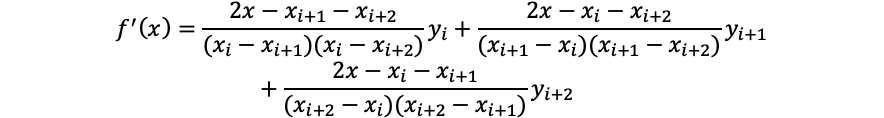

Segunda derivada:

Polinomio de Lagrange de tercer orden:


$$\begin{array}{l}
{f^{\prime } }^{\prime } \left(x\right)=\;\frac{2y_i \;}{\left(x_{i+2} -x_i \right)\left(x_{i-1} -x_i \right)}+\frac{2y_i }{\left(x_{i+2} -x_i \right)\left(x_{i+1} -x_i \right)}+\frac{2y_i }{\left(x_{i-1} -x_i \right)\left(x_{i+1} -x_i \right)}-\frac{2y_{i+2} \;\left(x_{i-1} -x_i \right)\;}{\left(x_{i+2} -x_{i-1} \right)\left(x_{i+2} -x_{i+1} \right)\left(x_{i+2} -x_i \right)\;}-\\
\;\;\;\;\;\;\;\;\;\;\;\;\;-\;\frac{2y_{i+2} \;\left(x_{i+1} -x_i \right)}{\left(x_{i+2} -x_{i-1} \right)\left(x_{i+2} -x_{i+1} \right)\left(x_{i+2} -x_i \right)}-\frac{2y_{i+1} \;\left(x_{i+2} -x_i \right)}{\left(x_{i+2} -x_{i+1} \right)\left(x_{i-1} -x_{i+1} \right)\left(x_{i+1} -x_i \right)}-\frac{2y_{i+1} \;\left(x_{i-1} -x_i \right)}{\left(x_{i+2} -x_{i+1} \right)\left(x_{i-1} -x_{i+1} \right)\left(x_{i+1} -x_i \right)}+\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\frac{2y_{i-1} \;\left(x_{i+2} -x_i \right)}{\left(x_{i+2} -x_{i-1} \right)\left(x_{i-1} -x_{i+1} \right)\left(x_{i-1} -x_i \right)}+\frac{2y_{i-1} \;\left(x_{i+1} -x_i \right)}{\left(x_{i+2} -x_{i-1} \right)\left(x_{i-1} -x_{i+1} \right)\left(x_{i-1} -x_i \right)}\;
\end{array}$$


**b)**

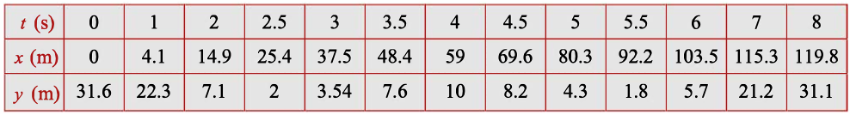

clc, clear, clf

% Datos del problema 
t = [0 1 2 2.5 3 3.5 4 4.5 5 5.5 6 7 8]';
x = [0 4.1 14.9 25.4 37.5 48.4 59 69.6 80.3 92.2 103.5 115.3 119.8]';
y = [31.6 22.3 7.1 2 3.54 7.6 10 8.2 4.3 1.8 5.7 21.2 31.1]';

% Cálculo de las primeras y segundas derivadas de x e y
[dx, ddx] = PySDerDes(t, x);
[dy, ddy] = PySDerDes(t, y);

**b.1)**

 $v=\;\sqrt{\left(v_x^2 +v_y^2 \right)}$ siendo $v_x =\frac{\textrm{dx}}{\textrm{dt}}$ y $v_y =\frac{\textrm{dy}}{\textrm{dt}}$

 $a=\sqrt{\left(a_x^2 +a_y^2 \right)}$ siendo $a_x =\frac{d^2 x}{dt^2 }$ y $a_y =\frac{d^2 y}{dt^2 }$

v = sqrt(dx.^2 + dy.^2); % Velocidad
a = sqrt(ddx.^2 + ddy.^2); % Aceleración

T = table(t, x, y , v, a);
T.Properties.VariableNames = {'t(s)', 'x(m)', 'y(m)', 'v(m/s)', 'a(m/s^2)'}

T = 13×5 table
    t(s)    x(m)     y(m)    v(m/s)    a(m/s^2)
    ____    _____    ____    ______    ________

      0         0    31.6    6.3941     21.039 
      1       4.1    22.3    14.338     8.9275 
      2      14.9     7.1    21.227     16.575 
    2.5      25.4       2    22.879      27.32 
      3      37.5    3.54    23.672     11.165 
    3.5      48.4     7.6     22.45     6.7476 
      4        59      10    21.208       16.8 
    4.5      69.6     8.2    22.049     8.4095 
      5      80.3     4.3    23.489     7.3756 
    5.5      92.2     1.8    23.242     25.712 
      6     103.5     5.7    21.644     20.758 
      7     115.3    21.2     15.09     9.2005 
      8     119.8    31.1    7.1507      24.67 


**b.2)**

Gráfica con el desplazamiento:$y\;=\;f\left(x\right)$ 

subplot(3,1,1)
plot(x, y, 'b','LineWidth',2);
hold on
plot(x, y, 'or', 'LineWidth',1.5)
ylabel('y (m)');
xlabel('x (m)');
grid on
title('y = f(x)')
hold off

Gráfica con la velocidad: $v=v\left(t\right)$

subplot(3,1,2)
plot(t, v, 'b', 'LineWidth', 2);
hold on
plot(t, v, 'or', 'LineWidth',1.5)
ylabel('v (m/s)');
xlabel('t (s)');
grid on
title('v = v(t)')
hold off

Gráfica con la aceleración: $a=a\left(t\right)$

subplot(3,1,3)
plot(t, a, 'b', 'LineWidth', 2);
hold on
plot(t, a, 'or', 'LineWidth',1.5)
ylabel('a (m/s^2)');
xlabel('t (s)');
grid on
title('a = a(t)')
hold off

## P04_T06_P03. Derivación mediante la extrapolación de Richardson

### Respuesta

**a) **Función Adjuntada:  `[dfdx,d2fdx] = DerRichardson(f,x0,hin,N)`

**b) **

clc, clear

% Datos del problema
f = @(x) x .* exp(x);
x0 = 2;
hin = 0.4;
N = 4;

% Cáluclo de las primeras y segundas derivadas
[dfdx, d2fdx] = DerRichardson(f, x0, hin, N);
fprintf('Primera derivada en x = 2 :')

Primera derivada en x = 2 :

disp(dfdx)

    0.4000   23.1635         0         0         0
    0.2000   22.4142   22.1644         0         0
    0.1000   22.2288   22.1670   22.1672         0
    0.0500   22.1826   22.1672   22.1672   22.1672



fprintf('Segunda derivada en x = 2 :')

Segunda derivada en x = 2 :

disp(d2fdx)

    0.4000   30.1516         0         0         0
    0.2000   29.7043   29.5552         0         0
    0.1000   29.5932   29.5562   29.5562         0
    0.0500   29.5655   29.5562   29.5562   29.5562



Podemos calcular el error que se produce al no calcular la derivada en el punto con MATLAB, para ello empleamos la función en forma simbólica y hallamos la derivada en el punto.

syms x;

primera = diff(f, x);
segunda = diff(f, x, 2);

primeras = double(subs(primera, x, x0));
segundas = double(subs(segunda, x, x0));


error1 = double(abs(dfdx(end, end) - primeras) * 100);
error2 = double(abs(d2fdx(end, end) - segundas) * 100);


datos = ['Primera'; 'Segunda'];
derivadasRich = [dfdx(end, end); d2fdx(end, end) ];
derivadasMatlab = [primeras; segundas];
errores = [ error1; error2];

T = table(datos, derivadasRich, derivadasMatlab, errores);
T.Properties.VariableNames = {'Derivada', 'derivada Richardson', ' derivada Matlab', 'Error derivadas %'}

T = 2×4 table
    Derivada    derivada Richardson     derivada Matlab    Error derivadas %
    ________    ___________________    ________________    _________________

    Primera           22.167                22.167            3.5957e-09    
    Segunda           29.556                29.556            1.1003e-09    


## P04_T06_P04. Primeras derivadas parciales

### Respuesta

**a) **Funcción adjuntada:  `[dfdx,dfdy] = PrmDerPar(x,y,f)`

**b)**

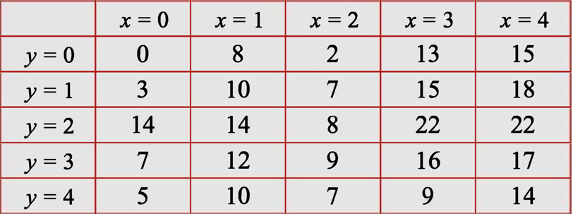

clc, clear

% Datos del problema 
u = [ 0 8 2 13 15; 
      3 10 7 15 18; 
      14 14 8 22 22;
      7 12 9 16 17; 
      5 10 7 9 14];
x = [0 1 2 3 4];
y = [0 1 2 3 4];

Cálculo de las derivadas parciales $\frac{\partial }{\partial x}u,\frac{\partial }{\partial y}u$

[dudx,dudy] = PrmDerPar(x,y,u)

dudx =    -1.0000    1.0000    7.0000   -0.5000    2.5000
    3.5000    1.5000    1.5000    2.2500    1.7500
    1.0000    0.5000    0.5000    0.2500   -0.2500
   -2.2500   -1.0000   -0.2500   -3.2500   -2.0000
    0.5000   -2.0000   -3.5000   -7.5000   -2.0000


dudy =    15.0000    0.5000    1.2500    3.2500   -2.5000
   12.0000    1.0000    1.2500    2.7500    0.5000
    3.0000   -1.5000    2.0000    3.5000   -7.0000
    9.0000    0.5000    1.0000    2.0000   -2.0000
    9.0000    0.5000   -0.2500    1.7500    6.5000
